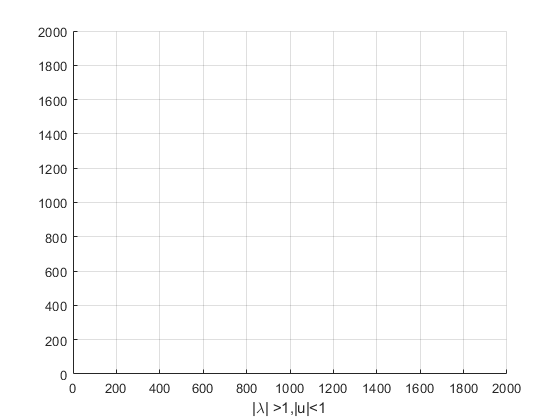

% 捕食者-被捕食者解的图像表示
clear, clc
a = -20*100; b = -a; c = a; d = b; p = 0.1;	%确定画图范围
n = 100;	%序列迭代次数
xlabel('|\lambda| >1,|u|<1') 
axis([0 b 0 d]), grid on, hold on 

x = linspace(a,b,30);
A = [0.5 0.4;-0.104 1.1]	%特征值绝对值<1

A =     0.5000    0.4000
   -0.1040    1.1000


[pc,lambda] = eig(A)	%求 A 的特征值和对应的特征向量

pc =    -0.9806   -0.6097
   -0.1961   -0.7926


lambda =     0.5800         0
         0    1.0200


[Y,I] = sort(diag(abs(lambda)),'descend')	%对特征值的绝对值降序排列 

Y =     1.0200
    0.5800


I =      2
     1


temp = diag(lambda)

temp =     0.5800
    1.0200


lambda = temp(I)	%输出按特征值的绝对值降序排列的特征值

lambda =     1.0200
    0.5800


pc = -pc(:,I)

pc =     0.6097    0.9806
    0.7926    0.1961


z1 = pc(2,1)/pc(1,1)*x	%特征向量 v1

z1 = 	1.0e+03 *

   -2.6000   -2.4207   -2.2414   -2.0621   -1.8828   -1.7034   -1.5241   -1.3448   -1.1655   -0.9862   -0.8069   -0.6276   -0.4483   -0.2690   -0.0897    0.0897    0.2690    0.4483    0.6276    0.8069    0.9862    1.1655    1.3448    1.5241    1.7034    1.8828    2.0621    2.2414    2.4207    2.6000


z2 = pc(2,2)/pc(1,2)*x	%特征向量 v2 

z2 =  -400.0000 -372.4138 -344.8276 -317.2414 -289.6552 -262.0690 -234.4828 -206.8966 -179.3103 -151.7241 -124.1379  -96.5517  -68.9655  -41.3793  -13.7931   13.7931   41.3793   68.9655   96.5517  124.1379  151.7241  179.3103  206.8966  234.4828  262.0690  289.6552  317.2414  344.8276  372.4138  400.0000


h = plot(x,z1),set(h,'linewidth',2), text(x(7),z1(7)-100,'v1')

h =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×30 double]
              YData: [1×30 double]
              ZData: [1×0 double]

  显示 所有属性


h = plot(x,z2),set(h,'linewidth',2), text(x(20),z2(20)-100,'v2') 

h =   Line - 属性:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×30 double]
              YData: [1×30 double]
              ZData: [1×0 double]

  显示 所有属性


button = 1;
while button == 1
    [xi yi button] = ginput(1);	%用鼠标选初始点
    plot(xi,yi,'go'),hold on
    X0 = [xi;yi];
    X = X0;
    for i=1:n
        X = [A*X, X0];	%用这种方式迭代，并画图 
        h = plot(X(1,1),X(2,1),'R.',X(1,1:2),X(2,1:2),'r-'); 
        hold on 
        text(X0(1,1),X0(2,1),'x0')
        quiver([X(1,2),1]',[X(2,2),1]',[X(1,1)-X(1,2),0]',[X(2,1)-X(2,2),0]',p)
        set(h,'MarkerSize',6),grid,
    end
end

错误使用 ginput (line 82)
已被图窗删除操作中断